# Go to point with DSMR

**Authors:**

- Alejandro, Kenny

- Crespo, Nil

- Hossain,Tanvir

**Supervisor:**

- Martinez, Antonio

## **1 Explanation** 

In this live script we are going to translate the "Go to point architecture of *sl_drivepoint *" made with simulink by Peter Corke into a secuential code using a DSMR.

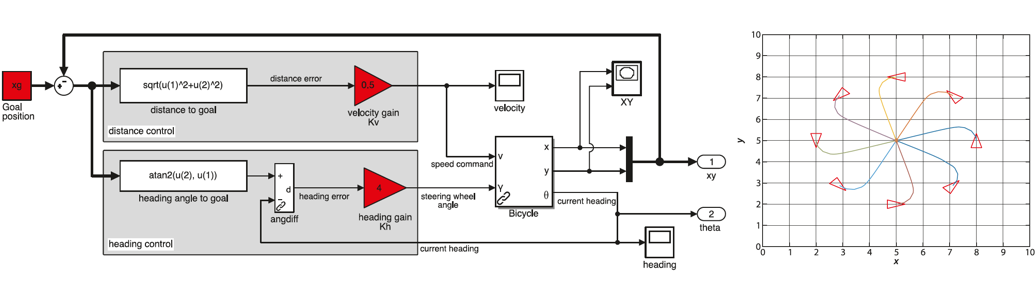

sl_drivepoint:

- It is express in simulink's language.

- Vehicle is a Bicycle.

Our version:

- It is a sequential code (using matlab's language).

- Vehicle is a DSMR(Differential Steering Mobile Robot).

## 2 Auxiliar functions

### **Invers Kinematics**

Find wheel's angular velocities from the velocity and steering


$$\left( {\begin{array}{*{20}{c}} {{{\dot \varphi }_r}} \\ {{{\dot \varphi }_l}} \end{array}} \right) =\frac{1}{r}\left( {\begin{array}{*{20}{c}} 1 \\  1 \end{array}} \right){}^{eR}{v_x} +\frac{1}{r} \left( {\begin{array}{*{20}{c}}  S \\ { - S} \end{array}} \right) \dot \psi 
= \frac{1}{r} \left[ {\begin{array}{*{20}{c}}
  {1&S \\ 
  {1&-S\\  
\end{array}} \right]
\left[ {\begin{array}{*{20}{c}}
  {{}^{eR}{v_x} }\\ 
  {\dot \psi }\\  
\end{array}} \right]$$
   

I_kine = @(v_x, psi,r,S) ...
[(1/r)*v_x+ (1/r)*S*psi (1/r)*v_x-(1/r)*S*psi];
w_s=I_kine(0,1,0.1,0.26)

w_s =     2.6000   -2.6000


### Odometry

Based on Forward Kinematics(Find the velocity and steering from wheel's angular velocities) 


$$ \[\left( {\begin{array}{*{20}{c}}
  {{\delta _d}} \\ 
  {{\delta _\theta }} 
\end{array}} \right) = \frac{r}{{2S}}\left( {\begin{array}{*{20}{c}}
  S&S \\ 
  1&{ - 1} 
\end{array}} \right)\left( {\begin{array}{*{20}{c}}
  \Delta\varphi_r \\ 
   \Delta\varphi_l  
\end{array}} \right)\]$$


odo = @(phi_r, phi_l,r,S,ts) ...
[(1/2)*r*(phi_r+phi_l)*ts (r/(2*S))*(phi_r-phi_l)*ts];
odo(-1,1,0.1,0.26,0.02)

ans =          0   -0.0077


Odometry from cumulative


$$\Delta_r=R_k-R_{k-1}\\
\Delta_l=L_k-L_{k-1}$$



$$ \[\left( {\begin{array}{*{20}{c}}
  {{\delta _d}} \\ 
  {{\delta _\theta }} 
\end{array}} \right) = \frac{1}{{2S}}\left( {\begin{array}{*{20}{c}}
  S&S \\ 
  1&{ - 1} 
\end{array}} \right)\left( {\begin{array}{*{20}{c}}
  \Delta_r \\ 
   \Delta_l  
\end{array}} \right)\]$$


odo = @(phi_r, phi_l,r,S,ts) ...
[(1/2)*r*(phi_r+phi_l)*ts (r/(2*S))*(phi_r-phi_l)*ts];
odometry = odo(-1,1,0.1,0.26,0.02)

odometry =          0   -0.0077


### Pose integration

$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuavP1wzZbItLDhis9
% wBH5garmWu51MyVXgaruWqVvNCPvMCaebbnrfifHhDYfgasaacH8sr
% ps0lbbf9q8WrFfeuY-ribbf9v8qqaqFr0xc9pk0xbba9q8WqFfea0-
% yr0RYxir-Jbba9q8aq0-yq-He9q8qqQ8frFve9Fve9Ff0dc9Gqpi0d
% meaabaqaciGacaGaaeqabaWaaeaaeaaakeaacqaH+oaEdaWgaaWcba
% Gaam4AaiabgUcaRiaaigdaaeqaaOGaeyypa0ZaaeWaaeaafaWabeGa
% baaabaGaamiCamaaBaaaleaacaWGRbGaey4kaSIaaGymaaqabaaake
% aacqaH4oqCdaWgaaWcbaGaam4AaiabgUcaRiaaigdaaeqaaaaaaOGa
% ayjkaiaawMcaaiabg2da9maabmaabaqbaeqabmqaaaqaaiaadIhada
% WgaaWcbaGaam4AaaqabaGccqGHRaWkcqaH0oazdaWgaaWcbaGaamiE
% aaqabaGccaWGJbGaeqiYdK3aaSbaaSqaaiaadUgaaeqaaaGcbaGaam
% yEamaaBaaaleaacaWGRbaabeaakiabgUcaRiabes7aKnaaBaaaleaa
% caWG4baabeaakiaadohacqaHipqEdaWgaaWcbaGaam4Aaaqabaaake
% aacqaHipqEdaWgaaWcbaGaam4AaaqabaGccqGHRaWkcqaH0oazdaWg
% aaWcbaGaeqiYdKhabeaaaaaakiaawIcacaGLPaaaaaa!5E74!
\[{\xi _{k + 1}} = \left( {\begin{array}{*{20}{c}}
  {{p_{k + 1}}} \\ 
  {{\theta _{k + 1}}} 
\end{array}} \right) = \left( {\begin{array}{*{20}{c}}
  {{x_k} + {\delta _x}c{\psi _k}} \\ 
  {{y_k} + {\delta _x}s{\psi _k}} \\ 
  {{\psi _k} + {\delta _\psi }} 
\end{array}} \right)\]$, keep in mind that $\theta_{k+1}$ goes from 0 to $2\pi$ 

Pose_int=@(X_ant,odo) ...
[X_ant(1)+odo(1)*cos(X_ant(3)) ...
 X_ant(2)+odo(1)*sin(X_ant(3)) ...
 X_ant(3)+odo(2)];

## **3 GoTo Point Implementation**

Before executing this section reproduce the previous secction "Auxiliar functions"

startPose = [0,0,0]; % startPose x y theta 
goal = [2,3]; % goal position

Kv = 0.9; % Velocity Gain
Kh = 4; % Head Gain
r = 0.1; % wheels radius
S = 0.26; % half of the distance between the wheels' center  
ts = 0.02;% sample time

currentPose = startPose;
stop = false;
figure
scatter(goal(1),goal(2));
hold on
scatter(startPose(1),startPose(2));
xlabel('x');
ylabel('y');
title('Go To Point')
grid
axis([-5 5 -5 5])
xticks(-5:5);
yticks(-5:5);
Robot.V = [0 -0.2 0;
           0.4 0 0;
           0 0.2 0;];
Robot.F = [1,2,3];
fig_robot = [];

while (~stop)
    currentdiff = goal - currentPose([1,2]);
    %Velocity
    %distance to goal or distance error
    throttle = sqrt(currentdiff(1)^2 + currentdiff(2)^2); 
    if throttle < 0.1
        %we can stop is distance error is less than 0.1
        stop = true;
    else
        velocity = throttle *  Kv;
        %Psi
        %heading angle to goal
        steering = atan2(currentdiff(2),currentdiff(1));
        %heading error
        anglesdiff = angdiff(steering,currentPose(3));
        psi = anglesdiff * Kh; 
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%%%% Review %%%%%%
        % in theory [phi_r phi_l] = I_kine(vx,Psi,r,S);
        angular_velocitys = I_kine(velocity,psi,r,S);
        % However when  angular_velocitys(1) is asign to the phi_r, 
        % the robot goes in the oposite direction. 
        phi_l = angular_velocitys(2);
        phi_r = angular_velocitys(1);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        deltas = odo(phi_r,phi_l,r,S,ts);
        delta_d = deltas(1);
        delta_th = deltas(2);
        lastPose = currentPose;
        %Calculating new pose
        currentPose = Pose_int(currentPose,[delta_d,delta_th]);
        %Robot(red triangle)
        pose = transl(currentPose(1),currentPose(2),0)* trotz(currentPose(3));
        CG = (max(Robot.V) + min(Robot.V))/2;
        T = pose* transl(-CG);
        aux = [Robot.V ones(length(Robot.V'),1)]' ; 
        robot = (T * aux)';
        robot(:,4) = [];
        delete(fig_robot);
        fig_robot=patch("Faces",Robot.F,"Vertices",robot, 'FaceAlpha', 0, ...
             'EdgeColor',   [1,0,0]);
        pause(0.05);
        plot([lastPose(1),currentPose(1)],[lastPose(2),currentPose(2)],...
        'LineStyle',"-","Color",'blue');
    end
end
legend('goalPoint','startPoint','path');

We encapsulate the algoritm in a function called  **goToPoint(goal,startPose,Kv,Kh,minStopDistance), **which returns all the trajectory poses that are needed to go from the given startPose (position and orientation) to a less than a minStopDistance of the goal point.

## **4 Go To Point Applications**

### **Recreating image**

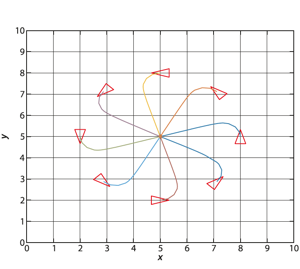

R = 3;
goal = [5,5];
figure
hold on;
title("Recreating Image");
Robot.V = [0 -0.2 0;
           0.4 0 0;
           0 0.2 0;];
Robot.F = [1,2,3];
Robot.V = Robot.V * 1;
axis([0 10 0 10]);
grid
xlabel("X");
ylabel("Y");
xticks(0:10);
yticks(0:10);

Kv = 0.9; % Velocity Gain
Kh = 4; % Head Gain
minStopDistance = 0.1;
for i = 1:8
    angle = (i-1)*pi/4; 
    startPose_origen= [cos(angle)*R,sin(angle)*R,pi/2 + (i-1)*pi/4];
    startPose = (transl(5,5,0) * [startPose_origen, 1]')';
    startPose(4) = [];
    poses = goToPoint(goal,startPose(1:3),Kv,Kh,minStopDistance);
    plot(poses(:,1),poses(:,2),"Color",rand(1,3));
    pose_matrix = transl(startPose(1),startPose(2),0)* trotz(startPose(3));
    CG = (max(Robot.V) + min(Robot.V))/2;
    T = pose_matrix*transl(-CG);
    aux = [Robot.V ones(length(Robot.V'),1)]' ; 
    robot = (T * aux)';
    robot(:,4) = [];
    fig_robot=patch("Faces",Robot.F,"Vertices",robot, 'FaceAlpha', 0, ...
             'EdgeColor',   [1,0,0]);
end
hold off

### **Following a trajectory with waypoints**

In this case we are going to make trajectory by following a list of waypoints 

% clear
load 'way_points_2.mat' wp
% Calculate all the intermidiate points to the 
n_points= size(wp, 2);
startPose = wp(:,1)';
startPose(3) = 0 ;
poses = [];
figure
%Drawing all the waypoints
scatter(wp(1,:), wp(2,:),'Marker','o','MarkerEdgeColor','b');
title('Following a trayectory with waypoints');
hold on;
axis equal
grid
xlabel("X");
ylabel("Y");

Robot.V = [0 -0.2 0;
           0.4 0 0;
           0 0.2 0;];
Robot.F = [1,2,3];
Robot.V = Robot.V * 20;
fig_robot = [];
Kv = 0.9; % Velocity Gain
Kh = 4; % Head Gain
minStopDistance = 2;
for i = 2:n_points;
    goal = wp(:,i)';
    poses_current = goToPoint(goal,startPose,Kv,Kh,minStopDistance);
    for j = 1:size(poses_current,1)-1
        pose_matrix = transl(poses_current(j,1),poses_current(j,2),0)*trotz(poses_current(j,3));
        CG = (max(Robot.V) + min(Robot.V))/2;
        T = pose_matrix*transl(-CG);
        aux = [Robot.V ones(length(Robot.V'),1)]' ; 
        robot = (T * aux)';
        robot(:,4) = [];
        delete(fig_robot);
        fig_robot=patch("Faces",Robot.F,"Vertices",robot, 'FaceAlpha', 0, ...
                 'EdgeColor',   [1,0,0]);
        plot(poses_current(j:j+1,1),poses_current(j:j+1,2),"Color",'c');
%       pause(0.05);
    end
    pause(0.05);
    startPose = poses_current(end,:);
    poses  = [poses; poses_current];
end
legend('waypoints','path');

## **Code Generator**

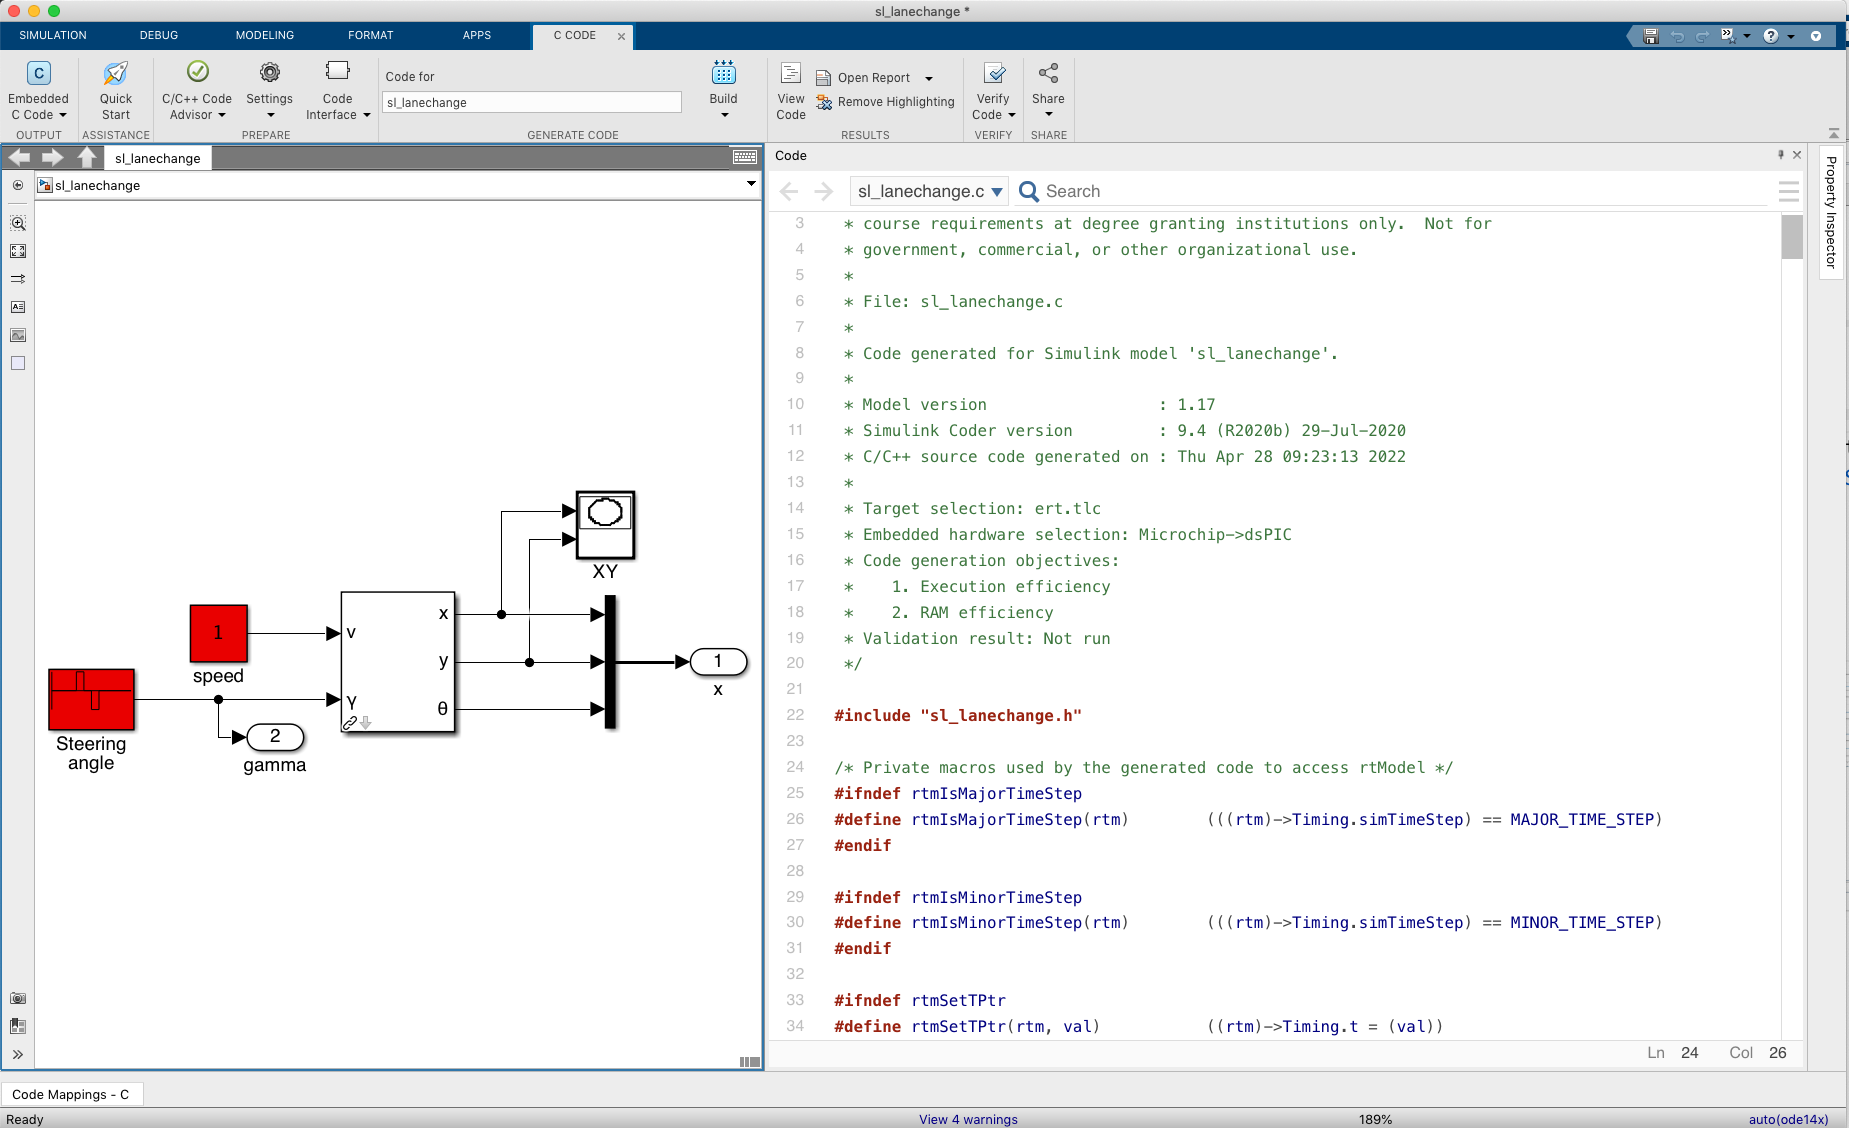

load way_points_2.mat

n_waypoints = size(wp, 2)

n_waypoints = 35


% Define the goal points
goalPoints = wp

goalPoints =   -33.2412  -33.2412  -33.1066  -33.3758  -33.1066  -32.7029  -32.0299  -31.8953  -23.9545  -17.2251   -9.1497   -5.5158   -2.8240   -1.4781   -2.2856   -3.7661    0.1370    5.2514    2.6942    0.2716   -1.6127    1.4829    8.3469   14.9418   25.3052   27.3241   31.3617   37.4183   42.9364   40.1101   34.7265   29.7467   25.3052   18.5757    8.7507
   38.2708   34.6515   28.4852   20.9785   14.1421    5.8311   -3.2842  -12.3995  -15.0804  -13.8740  -13.7400  -13.8740  -15.0804  -17.7614  -22.0510  -26.7426  -28.7534  -25.1341  -20.0402  -17.6274  -14.2762  -12.1314  -11.5952  -13.2038  -15.3485  -15.0804  -14.9464  -13.8740  -12.5335   -9.7185   -9.1823   -8.3780   -7.9759   -7.7078   -6.7695



% Define the start pose
startPose = [0, 0];

% Define the control gains
Kv = 0.9;
Kh = 4;

% Define the minimum stopping distance
minStopDistance = 0.1;

% Initialize the poses array
poses = [];
start = wp(:,1)';

% Loop through the goal points and call the goToPoint function
for i = 2:n_waypoints
    goal = goalPoints(:,i)';
    
    % Call the goToPoint function
    traj = goToPoint(goal, start, Kv, Kh, minStopDistance);
    
    start = traj(end,:);
    % Append the poses to the overall trajectory
    poses = [poses; traj];
end

Index in position 2 exceeds array bounds. Index must not exceed 2.

Error in 2_GoToPoint_DSMR>goToPoint (line 249)
        anglesdiff = angdiff(steering,currentPose(end,3));


% Plot the trajectory
plot(poses(:,1), poses(:,2));

## **5 Function **

function [poses] = goToPoint(goal,startPose,Kv,Kh,minStopDistance)
%   Input:
%     goal - goal point
%     startPose - vehicles' start pose
%     Kv - Velocity Gain
%     Kh - % Head Gain
%     minStopDistance - minStopDistance to the goal point to consider that
%     we have arrived to the goal.
%   Output: all the poses from startPose until it arrive to a less than
%   minStopDistance to goal

    I_kine = @(v_x, psi,r,S) ...
    [(1/r)*v_x+ (1/r)*S*psi (1/r)*v_x-(1/r)*S*psi];
    
    odo = @(phi_r, phi_l,r,S,ts) ...
    [(1/2)*r*(phi_r+phi_l)*ts (r/(2*S))*(phi_r-phi_l)*ts];
    
    Pose_int=@(X_ant,odo) ...
    [X_ant(1)+odo(1)*cos(X_ant(3)) ...
     X_ant(2)+odo(1)*sin(X_ant(3)) ...
     X_ant(3)+odo(2)];
   
    r = 0.1; % wheels radius
    S = 0.26; % half of the distance between the wheels' center
    ts = 0.02;% sample time

    currentPose = startPose;  
    stop = false;
    while (~stop)
    currentdiff = goal - currentPose(end,[1,2]);
    %Velocity
    %distance to goal or distance error
    throttle = sqrt(currentdiff(1)^2 + currentdiff(2)^2); 

    if throttle < minStopDistance 
        stop = true;
    else
        velocity = throttle *  Kv;
        %Psi
        %heading angle to goal
        steering = atan2(currentdiff(2),currentdiff(1));
        %heading error
        anglesdiff = angdiff(steering,currentPose(end,3));
        psi = anglesdiff * Kh;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%%%% Review %%%%%%
        % in theory [phi_r phi_l] = I_kine(vx,Psi,r,S);
        angular_velocitys = I_kine(velocity,psi,r,S);
        % However when angular_velocitys(1) is asign to the phi_r, 
        % the robot goes in the oposite direction. 
        phi_l = angular_velocitys(2);
        phi_r = angular_velocitys(1);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        deltas = odo(phi_r,phi_l,r,S,ts);
        delta_d = deltas(1);
        delta_th = deltas(2);
        %Calculating new pose
        currentPose = [currentPose; Pose_int(currentPose(end,:),[delta_d,delta_th])];
     end
    end
    poses = currentPose;
end